# Model manipulation

**Author(s): Vanja Vlasov, Systems Biochemistry Group, LCSB, University of Luxembourg,**

**Thomas Pfau,  Systems Biology Group, LSRU, University of Luxembourg.**

**Reviewer(s): Ines Thiele, Systems Biochemistry Group, LCSB, University of Luxembourg. **

**Catherine Clancy, Systems Biochemistry Group, LCSB, University of Luxembourg.**

**Stefania Magnusdottir, Molecular Systems Physiology Group, LCSB, University of Luxembourg.**

## INTRODUCTION

In this tutorial, we will do a manipulation with a simple model of the first few reactions of the glycolysis metabolic pathway as created in the "Model Creation" tutorial.

Glycolysis is the metabolic pathway that occurs in most organisms in the cytosol of the cell. First, we will use the beginning of that pathway to create a simple constraint-based metabolic network (Figure 1).

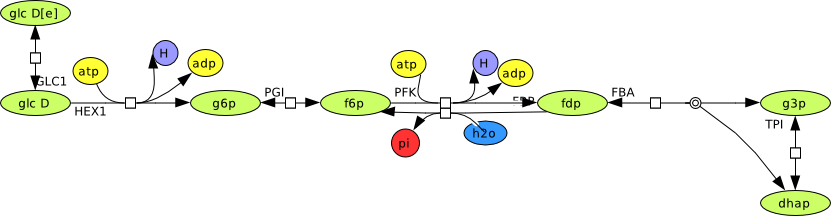

                                                                   Figure 1: A small metabolic network consisting of the seven reactions in the glycolysis pathway. 

At the beginning of the reconstruction, the initial step is to assess the integrity of the draft reconstruction. Furthermore, an evaluation of accuracy is needed: check necessity of each reaction and metabolite,  the accuracy of the stoichiometry, and direction and reversibility of the reactions.

The metabolites structures and reactions are from the Virtual Metabolic Human database (VMH, [http://vmh.life](http://vmh.life/)).

After creating or loading the model and to simulate different model conditions, the model can be modified, such as:

- Creating, adding and handling reactions;

- Adding exchange, sink and demand reactions;

- Altering reaction bounds;

- Altering reactions;

- Removing reactions and metabolites;

- Searching for duplicates and comparison of two models;

- Changing the model objective;

- Changing the direction of reaction(s);

- Creating gene-reaction-associations ('GPRs');

- Extracting a subnetwork

## EQUIPMENT SETUP

Start CobraToolbox

initCobraToolbox;



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2017
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done.
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules ... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > Retrieving models ...   Done.
 > TranslateSBML is installed and working properly.
 > Configuring sol

## PROCEDURE

## Generate a network

A constraint-based metabolic model contains the stoichiometric matrix ($$S$) with reactions and metabolites [1].

$$S$ is a stoichiometric representation of metabolic networks corresponding to the reactions in the biochemical pathway. In each column of the $$S$ is a biochemical reaction ($$n$) and in each row is a precise metabolite ($$m$). There is a stoichiometric coefficient of zero, which means that metabolite does not participate in that distinct reaction. The coefficient also can be positive when the appropriate metabolite is produced, or negative for every metabolite consumed [1].

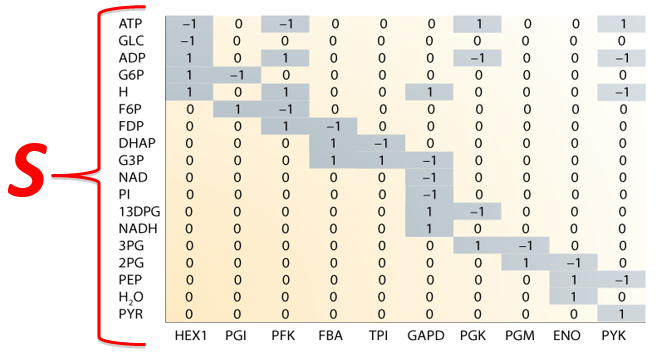

Generate a model using the `createModel()` function:

ReactionFormulas = {'glc_D[e]  -> glc_D[c]',...
    'glc_D[c] + atp[c]  -> h[c] + adp[c] + g6p[c]',...
    'g6p[c]  <=> f6p[c]',...
    'atp[c] + f6p[c]  -> h[c] + adp[c] + fdp[c]',...
    'fdp[c] + h2o[c]  -> f6p[c] + pi[c]',...
    'fdp[c]  -> g3p[c] + dhap[c]',...
    'dhap[c]  -> g3p[c]'};
ReactionNames = {'GLCt1r', 'HEX1', 'PGI', 'PFK', 'FBP', 'FBA', 'TPI'};
lowerbounds = [-20, 0, -20, 0, 0, -20, -20];
upperbounds = [20, 20, 20, 20, 20, 20, 20];
model = createModel(ReactionNames, ReactionNames, ReactionFormulas,...
                   'lowerBoundList', lowerbounds, 'upperBoundList', upperbounds);

GLCt1r	glc_D[e] 	<=>	glc_D[c] 


HEX1	glc_D[c] + atp[c] 	->	h[c] + adp[c] + g6p[c] 


PGI	g6p[c] 	<=>	f6p[c] 


PFK	atp[c] + f6p[c] 	->	h[c] + adp[c] + fdp[c] 


FBP	fdp[c] + h2o[c] 	->	f6p[c] + pi[c] 


FBA	fdp[c] 	<=>	g3p[c] + dhap[c] 
TPI	dhap[c] 	<=>	g3p[c] 


We can now have a look at the different model fields created. The stoichiometry is stored in the $$S$ field of the model, which was described above. Since this is commonly a sparse matrix (i.e. it contains a lot of zeros), it may be useful for your understanding to display the full representation:

full(model.S)

ans =     -1     0     0     0     0     0     0
     1    -1     0     0     0     0     0
     0    -1     0    -1     0     0     0
     0     1     0     1     0     0     0
     0     1     0     1     0     0     0
     0     1    -1     0     0     0     0
     0     0     1    -1     1     0     0
     0     0     0     1    -1    -1     0
     0     0     0     0    -1     0     0
     0     0     0     0     1     0     0


It is required for a model to consist of the descriptive fields: `model.mets` and `model.rxns,` which represent the metabolites and the reactions respectively. 

model.mets

ans =     'glc_D[e]'
    'glc_D[c]'
    'atp[c]'
    'h[c]'
    'adp[c]'
    'g6p[c]'
    'f6p[c]'
    'fdp[c]'
    'h2o[c]'
    'pi[c]'
    'g3p[c]'
    'dhap[c]'


model.rxns

ans =     'GLCt1r'
    'HEX1'
    'PGI'
    'PFK'
    'FBP'
    'FBA'
    'TPI'


The fields in a COBRA model are commonly column vectors, which is important to note when writing functions manipulating these fields.

There are a few more fields present in each COBRA model:

`model.lb`, indicating the lower bounds of each reaction, and `model.ub` indicating the upper bound of a reaction.  

% this displays an array with reaction names and flux bounds.
[{'Reaction ID', 'Lower Bound', 'Upper Bound'};...   
 model.rxns, num2cell(model.lb), num2cell(model.ub)]

ans =     'Reaction ID'    'Lower Bound'    'Upper Bound'
    'GLCt1r'         [        -20]    [         20]
    'HEX1'           [          0]    [         20]
    'PGI'            [        -20]    [         20]
    'PFK'            [          0]    [         20]
    'FBP'            [          0]    [         20]
    'FBA'            [        -20]    [         20]
    'TPI'            [        -20]    [         20]


% This is a convenience function which does pretty much the same as the line above.
printFluxBounds(model);

Reaction ID	   Lower Bound	   Upper Bound
     GLCt1r	       -20.000	        20.000
       HEX1	         0.000	        20.000
        PGI	       -20.000	        20.000
        PFK	         0.000	        20.000
        FBP	         0.000	        20.000
        FBA	       -20.000	        20.000
        TPI	       -20.000	        20.000


Before we start to modify the model, it might be useful to store in the workspace some of the current properties of the model:

mets_length = length(model.mets)

mets_length = 12

rxns_length = length(model.rxns)

rxns_length = 7

## Creating, adding and handling reactions

If we want to add a reaction to the model or modify an existing reaction use the function `addReaction`. 

We will add to the model some more reactions from glycolysis. There are two different approaches to adding reactions to a model:

- The formula approach

- The list appraoch

**The formula approach**

model = addReaction(model, 'GAPDH',...
       'reactionFormula', 'g3p[c] + nad[c] + 2 pi[c] -> nadh[c] + h[c] + 13bpg[c]');

GAPDH	2 pi[c] + g3p[c] + nad[c] 	->	h[c] + nadh[c] + 13bpg[c] 


model = addReaction(model, 'PGK',...
       'reactionFormula', '13bpg[c] + adp[c] -> atp[c] + 3pg[c]');

PGK	adp[c] + 13bpg[c] 	->	atp[c] + 3pg[c] 


model = addReaction(model, 'PGM', 'reactionFormula', '3pg[c] <=> 2pg[c]' );

PGM	3pg[c] 	<=>	2pg[c] 


Display the stoichiometric matrix after adding reactions (note the enlarge link when you move your mouse over the output to display the full matrix):

full(model.S) 

ans =     -1     0     0     0     0     0     0     0     0     0
     1    -1     0     0     0     0     0     0     0     0
     0    -1     0    -1     0     0     0     0     1     0
     0     1     0     1     0     0     0     1     0     0
     0     1     0     1     0     0     0     0    -1     0
     0     1    -1     0     0     0     0     0     0     0
     0     0     1    -1     1     0     0     0     0     0
     0     0     0     1    -1    -1     0     0     0     0
     0     0     0     0    -1     0     0     0     0     0
     0     0     0     0     1     0     0    -2     0     0


- one extra column is added (for added reaction) and 5 new rows (for nadh, nad, 13bpg, 2pg and 3pg metabolites)

If you want to search for the indecies of reactions in the model, and change the order of the select reactions, use the following functions:

rxnID = findRxnIDs(model, model.rxns)

rxnID =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


model.rxns

ans =     'GLCt1r'
    'HEX1'
    'PGI'
    'PFK'
    'FBP'
    'FBA'
    'TPI'
    'GAPDH'
    'PGK'
    'PGM'


model = moveRxn(model, 8, 1);
model.rxns

ans =     'GAPDH'
    'GLCt1r'
    'HEX1'
    'PGI'
    'PFK'
    'FBP'
    'FBA'
    'TPI'
    'PGK'
    'PGM'


While the function `moveRxn` does not modify the network structure it can be useful in keeping a model tidy.

**The list approach**

model = addReaction(model, 'GAPDH2',...
    'metaboliteList', {'g3p[c]', 'nad[c]', 'pi[c]', '13bpg[c]', 'nadh[c]', 'h[c]' },...
    'stoichCoeffList', [-1; -1; -2; 1; 1; 1], 'reversible', false);

-  The `addReaction` function has the ability to recognize duplicate reactions. No reaction added here since the reaction is recognised to already exist in the model. 

Since the fourth reaction we attempted to add to the model was a duplicate, the number of the reactions in the model should only of increased by three and the number of metabolites in the model should of only increaed by five (13bpg, nad, nadh, 23bpg and 2pg).

assert(length(model.rxns) == rxns_length + 3)
assert(length(model.mets) == mets_length + 5) 

## Adding exchange, sink and demand reactions

The are three specific types of reactions in a COBRA model that use and recycle accumulated metabolites, or produce the required metabolites:

- *Exchange reactions *- are reactions that move metabolites across *in silico *compartments. These *in silico *compartments are representive of intra- and inter- cellular membranes.

- *Sink reactions* - The metabolites, produced in reactions that are outside of an ambit of the system or in unknown reactions, are supplied to the network with reversible sink reactions.

- *Demand reactions* - Irreversible reactions added to the model to consume metabolites that are deposited in the system.

There are two ways to implement these type of reactions:

- **Use the**` addReaction`** function, detailing the stoichiometric coefficient:**

model = addReaction(model, 'EX_glc_D[e]', 'metaboliteList', {'glc_D[e]'} ,...
                    'stoichCoeffList', [-1]);

EX_glc_D[e]	glc_D[e] 	<=>	


    To find exchange reactions in the model use the `findExcRxns` function:

% determines whether a reaction is a general exchange reaction and
% whether its an uptake.
[selExc, selUpt] = findExcRxns(model, 0, 1)

selExc =    0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1


selUpt =    0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


         **2.  Use a utility function to create the specific type of reaction: **`addExchangeRxn`**, **`addSinkReactions`**, **`addDemandReaction`**.**

model = addExchangeRxn(model, {'glc_D[e]', 'glc_D[c]'})

EX_glc_D[e]	glc_D[e] 	<=>	
EX_glc_D[c]	glc_D[c] 	<=>	


model =           rxns: {12×1 cell}
             S: [17×12 double]
            lb: [12×1 double]
            ub: [12×1 double]
             c: [12×1 double]
          mets: {17×1 cell}
             b: [17×1 double]
         rules: {12×1 cell}
         genes: {0×1 cell}
        osense: -1
        csense: [17×1 char]
    rxnGeneMat: [12×0 double]
      rxnNames: {12×1 cell}
    subSystems: {12×1 cell}
      metNames: {17×1 cell}
       grRules: {12×1 cell}


model = addSinkReactions(model, {'13bpg[c]', 'nad[c]'})

sink_13bpg[c]	13bpg[c] 	<=>	
sink_nad[c]	nad[c] 	<=>	


model =           rxns: {14×1 cell}
             S: [17×14 double]
            lb: [14×1 double]
            ub: [14×1 double]
             c: [14×1 double]
          mets: {17×1 cell}
             b: [17×1 double]
         rules: {14×1 cell}
         genes: {0×1 cell}
        osense: -1
        csense: [17×1 char]
    rxnGeneMat: [14×0 double]
      rxnNames: {14×1 cell}
    subSystems: {14×1 cell}
      metNames: {17×1 cell}
       grRules: {14×1 cell}


 model = addDemandReaction(model, {'dhap[c]', 'g3p[c]'})

DM_dhap[c]	dhap[c] 	->	
DM_g3p[c]	g3p[c] 	->	


model =           rxns: {16×1 cell}
             S: [17×16 double]
            lb: [16×1 double]
            ub: [16×1 double]
             c: [16×1 double]
          mets: {17×1 cell}
             b: [17×1 double]
         rules: {16×1 cell}
         genes: {0×1 cell}
        osense: -1
        csense: [17×1 char]
    rxnGeneMat: [16×0 double]
      rxnNames: {16×1 cell}
    subSystems: {16×1 cell}
      metNames: {17×1 cell}
       grRules: {16×1 cell}


## Setting a ratio between the reactions

It is important to emphasise that previous knowledge base information should be taken into account when generating a model. If this information is omited, the analysis of a model could be adversely altered and consequent results not representative of the network. 

For instance, if it is known that the flux of one reaction is *X* times the flux of another reaction, it is recommended to 'couple' (i.e., set a ratio) the reactions in the model. 

 E.g. $1\text{ }v\text{ }\text{EX}_\text{glc}_D\left\lbrack c\right\rbrack =2\text{ }v\text{ }\text{EX}_\text{glc}_D\left\lbrack e\right\rbrack$

model = addRatioReaction (model, {'EX_glc_D[c]', 'EX_glc_D[e]'}, [1; 2])

model =           rxns: {16×1 cell}
             S: [18×16 double]
            lb: [16×1 double]
            ub: [16×1 double]
             c: [16×1 double]
          mets: {18×1 cell}
             b: [18×1 double]
         rules: {16×1 cell}
         genes: {0×1 cell}
        osense: -1
        csense: [18×1 char]
    rxnGeneMat: [16×0 double]
      rxnNames: {16×1 cell}
    subSystems: {16×1 cell}
      metNames: {18×1 cell}
       grRules: {16×1 cell}
          note: 'EX_glc_D[c] andEX_glc_D[e]are set to have a ratio of1:2.'


## **Constraining the flux boundaries of a reaction**

In order to respect the transport and exchange potential of a particular metabolite, or to resemble the different conditions in the model, we frequently need to set appropriate limits of the reactions.

model = changeRxnBounds(model, 'EX_glc_D[e]', -18.5, 'l');

## Modifying reactions

The `addReaction` function is also a good choice to modify reactions. By supplying to the function a new stoichiometry, the old will be overwritten. 

For example, further up, we added the wrong stoichiometry for the GAP-Dehydrogenase with a coefficient of 2 for phosphate. Print the reaction to visulize:

printRxnFormula(model, 'rxnAbbrList', 'GAPDH');

GAPDH	2 pi[c] + g3p[c] + nad[c] 	->	h[c] + nadh[c] + 13bpg[c] 


Correct the reaction using `addReaction:` with the corrected stoichiometry:

model = addReaction(model, 'GAPDH',...
    'metaboliteList', {'g3p[c]', 'nad[c]', 'pi[c]', '13bpg[c]', 'nadh[c]','h[c]' },...
    'stoichCoeffList', [-1; -1; -1; 1; 1; 1]);

GAPDH	pi[c] + g3p[c] + nad[c] 	->	h[c] + nadh[c] + 13bpg[c] 


We can add a gene rule to the reaction using the `changeGeneAssociation` function: 

model = changeGeneAssociation(model, 'GAPDH', 'G1 and G2');

New gene G1 added to model
New gene G2 added to model


printRxnFormula(model, 'rxnAbbrList', {'GAPDH'}, 'gprFlag', true);

GAPDH	pi[c] + g3p[c] + nad[c] 	->	h[c] + nadh[c] + 13bpg[c] 	G1 and G2


Alternatively, one can add a gene rule to a reaction using the `addReaction` function, and within this function applying the `geneRule` input option. 

model = addReaction(model, 'PGK', 'geneRule', 'G2 or G3', 'printLevel', 0);

New gene G3 added to model


printRxnFormula(model, 'gprFlag', true);

GAPDH	pi[c] + g3p[c] + nad[c] 	->	h[c] + nadh[c] + 13bpg[c] 	G1 and G2
GLCt1r	glc_D[e] 	<=>	glc_D[c] 	
HEX1	glc_D[c] + atp[c] 	->	h[c] + adp[c] + g6p[c] 	
PGI	g6p[c] 	<=>	f6p[c] 	
PFK	atp[c] + f6p[c] 	->	h[c] + adp[c] + fdp[c] 	
FBP	fdp[c] + h2o[c] 	->	f6p[c] + pi[c] 	
FBA	fdp[c] 	<=>	g3p[c] + dhap[c] 	
TPI	dhap[c] 	<=>	g3p[c] 	
PGK	adp[c] + 13bpg[c] 	->	atp[c] + 3pg[c] 	G2 or G3
PGM	3pg[c] 	<=>	2pg[c] 	
EX_glc_D[e]	glc_D[e] 	<=>	2 Ratio_EX_glc_D[c]_EX_glc_D[e] 	
EX_glc_D[c]	glc_D[c] + Ratio_EX_glc_D[c]_EX_glc_D[e] 	<=>		
sink_13bpg[c]	13bpg[c] 	<=>		
sink_nad[c]	nad[c] 	<=>		
DM_dhap[c]	dhap[c] 	->		
DM_g3p[c]	g3p[c] 	->		


## Remove reactions and metabolites

To delete reactions from the model, use the `removeRxns` function:

 model = removeRxns(model, {'EX_glc_D[c]', 'EX_glc_D[e]', 'sink_13bpg[c]', ...
                             'sink_nad[c]', 'DM_dhap[c]', 'DM_g3p[c]'});

 assert(rxns_length + 3 == length(model.rxns));

- The reaction length was updated since a number of reactions were removed from the model. 

To remove metabolites from the model, use the `removeMetabolites()` function:

  model = removeMetabolites(model, {'3pg[c]', '2pg[c]'}, false);
  printRxnFormula(model, 'rxnAbbrList', {'GAPDH'}, 'gprFlag', true);

GAPDH	pi[c] + g3p[c] + nad[c] 	->	h[c] + nadh[c] + 13bpg[c] 	G1 and G2


- The '`GAPDH`' reaction is still present in the model since there are other metabolites in the reaction, not just the metabolites we tried to delete. The 'false' input option of the` removeMetabolites` function indictes that only empty reactions should be removed.

To delete metabolites and reactions with zero rows and columns, the `removeTrivialStoichiometry()` function can be used:

  model = removeTrivialStoichiometry(model)

model =           rxns: {9×1 cell}
             S: [15×9 double]
            lb: [9×1 double]
            ub: [9×1 double]
             c: [9×1 double]
          mets: {15×1 cell}
             b: [15×1 double]
         rules: {9×1 cell}
         genes: {3×1 cell}
        osense: -1
        csense: [15×1 char]
    rxnGeneMat: [9×3 double]
      rxnNames: {9×1 cell}
    subSystems: {9×1 cell}
      metNames: {15×1 cell}
       grRules: {9×1 cell}
          note: 'EX_glc_D[c] andEX_glc_D[e]are set to have a ratio of1:2.'


## Search for duplicate reactions and comparison of two models

Since genome-scale metabolic models are expanding every day [2], the need to compare models is also growing. The elementary functions in The Cobra Toolbox can support simultaneous structural analysis and comparison.

Checking for reaction duplicates with the `checkDuplicateRxn()` function (i.e. by reaction abbreviation), using either the method: 

- '`S`' (does not detect reverse reactions), or 

- '`FR`' (neglects reactions direction).

For demonstration of the S method, first check for dupicates and then add the duplicate reaction to the model:

[model, removedRxn, rxnRelationship] = checkDuplicateRxn(model, 'S', 1, 1);

Checking for reaction duplicates by stoichiometry ...
 no duplicates found.


printRxnFormula(model, 'rxnAbbrList', {'GLCt1r'});

GLCt1r	glc_D[e] 	<=>	glc_D[c] 


model = addReaction(model, 'GLCt1r_duplicate_reverse',...
                    'metaboliteList', {'glc_D[e]', 'glc_D[c]'},...
                    'stoichCoeffList', [1 -1], 'lowerBound', 0, ...
                    'upperBound', 20, 'checkDuplicate', 0);

GLCt1r_duplicate_reverse	glc_D[c] 	->	glc_D[e] 


Detecting duplicates using the S method:

method = 'S'; 
[model,removedRxn, rxnRelationship] = checkDuplicateRxn(model, method, 1, 1);

Checking for reaction duplicates by stoichiometry ...
 no duplicates found.


- The GLCt1r_duplicate_reverse reaction is not detected as a duplicate reaction therefore will not be removed as the S method does not detect a reverse reactions.

- Reevaluate the reaction length to show this:

assert(rxns_length + 3 == length(model.rxns));

Detecting duplicates using the FR method:

method = 'FR';
[model, removedRxn, rxnRelationship] = checkDuplicateRxn(model, method, 1, 1)

Checking for reaction duplicates by stoichiometry (up to orientation) ...
     Keep: 	GLCt1r	glc_D[e] 	<=>	glc_D[c] 
Duplicate: 	GLCt1r_duplicate_reverse	glc_D[c] 	->	glc_D[e] 


model =           rxns: {9×1 cell}
             S: [15×9 double]
            lb: [9×1 double]
            ub: [9×1 double]
             c: [9×1 double]
          mets: {15×1 cell}
             b: [15×1 double]
         rules: {9×1 cell}
         genes: {3×1 cell}
        osense: -1
        csense: [15×1 char]
    rxnGeneMat: [9×3 double]
      rxnNames: {9×1 cell}
    subSystems: {9×1 cell}
      metNames: {15×1 cell}
       grRules: {9×1 cell}
          note: 'EX_glc_D[c] andEX_glc_D[e]are set to have a ratio of1:2.'


removedRxn = 10

rxnRelationship = 2

assert(rxns_length + 2 == length(model.rxns))

- The GLCt1r_duplicate_reverse reaction is detected as a duplicate reaction therefore will not be removed as the FR method does detect a reverse reactions.

Checking for non-unique reactions and metabolites in a model using the` checkCobraModelUnique()` function: 

model = checkCobraModelUnique(model, false)

model =           rxns: {9×1 cell}
             S: [15×9 double]
            lb: [9×1 double]
            ub: [9×1 double]
             c: [9×1 double]
          mets: {15×1 cell}
             b: [15×1 double]
         rules: {9×1 cell}
         genes: {3×1 cell}
        osense: -1
        csense: [15×1 char]
    rxnGeneMat: [9×3 double]
      rxnNames: {9×1 cell}
    subSystems: {9×1 cell}
      metNames: {15×1 cell}
       grRules: {9×1 cell}
          note: 'EX_glc_D[c] andEX_glc_D[e]are set to have a ratio of1:2.'


- Input option 'false' means the function will not renames non-unique reaction names and metabolites

## Changing the model's objective

Simulating specific objectives of a model is often necessary in order to perform an investigation of different conditions. One of the fundamental objectives is optimal growth [3]. The model can be modified to get different conditions by changing the model objective.

One reaction is set as the objective, and has an objective coefficient of 0.5:

modelNew = changeObjective(model, 'GLCt1r', 0.5);

Multiple reactions are set collectively as the objective, and the default objective coefficient of 1 for each reaction:

modelNew = changeObjective(model, {'PGI'; 'PFK'; 'FBP'});

## The direction of reactions 

Sometimes it may be important to have all reactions in a model as irreversible reactions (i.e. only allow a forward reaction / positive flux in reactions). This can be important if, for example, the absolute flux values are of interest, and negative flux would reduce an objective while it should actually increase it. The COBRA Toolbox offers functionality to change all reactions in a model to an irreversible format. IT does this by splitting all reversible reactions and adjusting the respective lower and upper bounds, such that the model capacities stay the same. 

Let us see, how the glycolysis model currently looks:

printRxnFormula(model);

GAPDH	pi[c] + g3p[c] + nad[c] 	->	h[c] + nadh[c] + 13bpg[c] 
GLCt1r	glc_D[e] 	<=>	glc_D[c] 
HEX1	glc_D[c] + atp[c] 	->	h[c] + adp[c] + g6p[c] 
PGI	g6p[c] 	<=>	f6p[c] 
PFK	atp[c] + f6p[c] 	->	h[c] + adp[c] + fdp[c] 
FBP	fdp[c] + h2o[c] 	->	f6p[c] + pi[c] 
FBA	fdp[c] 	<=>	g3p[c] + dhap[c] 
TPI	dhap[c] 	<=>	g3p[c] 
PGK	adp[c] + 13bpg[c] 	->	atp[c] 


To convert a model to an irreversible model use the *convertToIrreversible* command:

[modelIrrev, matchRev, rev2irrev, irrev2rev] = convertToIrreversible(model);

Compare the irreversible model with the original model:

printRxnFormula(modelIrrev);

GAPDH	pi[c] + g3p[c] + nad[c] 	->	h[c] + nadh[c] + 13bpg[c] 
GLCt1r_f	glc_D[e] 	->	glc_D[c] 
HEX1	glc_D[c] + atp[c] 	->	h[c] + adp[c] + g6p[c] 
PGI_f	g6p[c] 	->	f6p[c] 
PFK	atp[c] + f6p[c] 	->	h[c] + adp[c] + fdp[c] 
FBP	fdp[c] + h2o[c] 	->	f6p[c] + pi[c] 
FBA_f	fdp[c] 	->	g3p[c] + dhap[c] 
TPI_f	dhap[c] 	->	g3p[c] 
PGK	adp[c] + 13bpg[c] 	->	atp[c] 
GLCt1r_b	glc_D[c] 	->	glc_D[e] 
PGI_b	f6p[c] 	->	g6p[c] 
FBA_b	g3p[c] + dhap[c] 	->	fdp[c] 
TPI_b	g3p[c] 	->	dhap[c] 


- You will notice, that there are more reactions in this model and that all reactions which have a lower bound < 0 are split in two. 

There is also a function to convert an irreversible model to a reversible model:

modelRev = convertToReversible(modelIrrev);

If we now compare the reactions of this model with those from the original model, they should look the same.

printRxnFormula(modelRev);

GAPDH	pi[c] + g3p[c] + nad[c] 	->	h[c] + nadh[c] + 13bpg[c] 
GLCt1r	glc_D[e] 	<=>	glc_D[c] 
HEX1	glc_D[c] + atp[c] 	->	h[c] + adp[c] + g6p[c] 
PGI	g6p[c] 	<=>	f6p[c] 
PFK	atp[c] + f6p[c] 	->	h[c] + adp[c] + fdp[c] 
FBP	fdp[c] + h2o[c] 	->	f6p[c] + pi[c] 
FBA	fdp[c] 	<=>	g3p[c] + dhap[c] 
TPI	dhap[c] 	<=>	g3p[c] 
PGK	adp[c] + 13bpg[c] 	->	atp[c] 


## Create gene-reaction-associations (GPRs) from scratch.

Assign the GPR '(G1) or (G2)' to the reaction HEX1

model = changeGeneAssociation(model, 'HEX1', '(G1) or (G2)');

## Replace an existing GPRs with a new one. 

Here, we will search for all instances of a specific GPR ('G1 and G2 ') and replace it with a new one ('G1 or G4').

Define the old and the new GPRs. 

GPRsReplace = {'G1 and G2'	'G1 or G4'};
for  i = 1 : size(GPRsReplace, 1)
    oldGPRrxns = find(strcmp(model.grRules, GPRsReplace{i, 1}));%Find all reactions that have the old GPR
    for j = 1:length(oldGPRrxns)
        model = changeGeneAssociation(model, model.rxns{oldGPRrxns(j)}, GPRsReplace{i, 2});
    end
end

New gene G4 added to model


## Remove unused genes

Let us assume that the reaction PGK has to be removed from the model

model = removeRxns(model, 'PGK');

The model now contains genes that do not participate in any GPR

find(sum(model.rxnGeneMat, 1) == 0)

ans = 3

We remove unused genes by re-assigning the model's GPR rules, which updates the reaction-gene-matrix and gene list.

Store GPR list in a new variable

storeGPR = model.grRules;

Erase model's gene list and reaction-gene-matrix

model.rxnGeneMat = [];
model.genes = [];

Re-assign GPR rules to model

for i = 1 : length(model.rxns)
    model = changeGeneAssociation(model, model.rxns{i}, storeGPR{i});
end

New gene G1 added to model
New gene G4 added to model


New gene G2 added to model


Check that there are no unused genes left in the model

find(sum(model.rxnGeneMat, 1) == 0)


ans =

  1×0 empty double row vector



## Remove issues with GPR definitions and spaces in reaction abbreviations

Remove issues with quotation marks in the GPR definitions.

model.grRules = strrep(model.grRules, '''', '');

Remove spaces from reaction abbreviations.

model.rxns = strrep(model.rxns, ' ', '');

Remove unneccessary brackets from the GPR associations. 

for i = 1 : length(model.grRules)
    if isempty(strfind(model.grRules{i}, 'and')) && isempty(strfind(model.grRules{i}, 'or'))% no AND or OR in GPR
        model.grRules{i} = regexprep(model.grRules{i}, '[\(\)]', '');
    end
end

## Extract subnetwork

Extract a subnetwork from the model consisting of the reactions HEX1, PGI, FBP, and FBA. The function will remove unused metabolites.

rxnList = {'HEX1'; 'PGI'; 'FBP'; 'FBA'}

rxnList =     'HEX1'
    'PGI'
    'FBP'
    'FBA'


subModel = extractSubNetwork(model, rxnList)

subModel =           rxns: {4×1 cell}
             S: [11×4 double]
            lb: [4×1 double]
            ub: [4×1 double]
             c: [4×1 double]
          mets: {11×1 cell}
             b: [11×1 double]
         rules: {4×1 cell}
         genes: {3×1 cell}
        osense: -1
        csense: [11×1 char]
    rxnGeneMat: [4×3 double]
      rxnNames: {4×1 cell}
    subSystems: {4×1 cell}
      metNames: {11×1 cell}
       grRules: {4×1 cell}
          note: 'EX_glc_D[c] andEX_glc_D[e]are set to have a ratio of1:2.'


## REFERENCES

[1] Orth, J. D., Thiele I., and Palsson, B. Ø. What is flux balance analysis? *Nat. Biotechnol., *28(3), 245-248 (2010).

[2] Feist, A. M., Palsson, B. Ø. The growing scope of applications of genome-scale metabolic reconstructions: the case of *E. coli*. *Nature Biotechnology, *26(6), 659-667 (2008).

[3] Feist, A. M., Palsson, B. Ø. The Biomass Objective Function. *Current Opinion in Microbiology, *13(3), 344-349 (2010).